cd(fileparts(matlab.desktop.editor.getActiveFilename))
pwd

ans = '/Users/ellarond/Dropbox/Papers/Neural plate fate choice/v3.0/Code'

addpath("utils")
plot_dir = fullfile('..', 'Plots');
if ~isfolder(plot_dir)
    mkdir(plot_dir);
end

CELL_SIZE = 5;
GRID_RES = 2; %number of cell_size within one grid element
bs = CELL_SIZE*GRID_RES; 

gene_ids = {'1P', '4N', 'Ptch2', 'pERK'};
gene_names = {'Wnt', 'Notch', 'Shh', 'FGF'};
target_channels = [3, 3, 3, 4];


map_dir = fullfile('Signal_maps');
%[mapavg_fns, mapavg_fn_path] = uigetfile('*.mat', "MultiSelect", "on");


atlas_sox19 = []; 
atlas_npsignal = []; 
std_npsignal = [];
sox19_thres = 0.25;

for k = 1:length(gene_ids)
    temp = load(fullfile(map_dir, [gene_ids{k}, '_map_avg.mat']));
    
    map_avg = temp.map_avg;
    atlas_sox19 = cat(3, atlas_sox19, map_avg.channel2.reg_mean_map);
end

mean_sox19 = mean(atlas_sox19, 3);
sox19_mask = 0*mean_sox19;
sox19_mask(mean_sox19 > sox19_thres) = 1;
%sox19_mask = imerode(sox19_mask, strel('square', 3));
%sox19_mask = imfill(sox19_mask, 'holes');
props = regionprops(sox19_mask, 'BoundingBox');
bb = uint8(props.BoundingBox);

for k = 1:length(gene_ids) %length(mapavg_fns)
    temp = load(fullfile(map_dir, [gene_ids{k}, '_map_avg.mat']));   
    map_avg = temp.map_avg;
    atlas_signal = map_avg.(['channel', num2str(target_channels(k))]).reg_mean_map;
    atlas_signal(sox19_mask == 0) = nan;
    atlas_signal = medfilt2(atlas_signal, [15 15]);
    atlas_npsignal = cat(3, atlas_npsignal, atlas_signal);
    num_samples = 3; 

    % full resolution std deviation
    std_npsignal = cat(3, std_npsignal, map_avg.(['channel', num2str(target_channels(k))]).std_map);
end
masked_atlas_nptf = bsxfun(@times, atlas_npsignal, sox19_mask);

masked_std_npsignal = [];
masked_std_npsignal = bsxfun(@times, std_npsignal, sox19_mask);

sox19_mask_stack = repmat(sox19_mask, 1, 1, size(masked_atlas_nptf, 3));

TRUNC_ROW_START = 131;
TRUNC_ROW_END = 580;
clipped_npsignal = masked_atlas_nptf;
clipped_npsignal(sox19_mask_stack == 0) = nan;
clipped_npsignal = clipped_npsignal(TRUNC_ROW_START:TRUNC_ROW_END, 1:size(clipped_npsignal, 2)/2, :);
npsignal_superpix = [];

clipped_std = masked_std_npsignal;
clipped_std = clipped_std(TRUNC_ROW_START:TRUNC_ROW_END, 1:size(clipped_std, 2)/2, :);
std_superpix = [];

s = size(clipped_npsignal);

clipped_sox19 = mean_sox19(TRUNC_ROW_START:TRUNC_ROW_END, 1:size(mean_sox19, 2)/2, :);
spx_sox19 = create_superpixels(clipped_sox19, [], bs);

spx_by_gene = zeros((s(1)/bs)*(s(2)/bs), s(3));
std_by_gene = zeros((s(1)/bs)*(s(2)/bs), s(3));


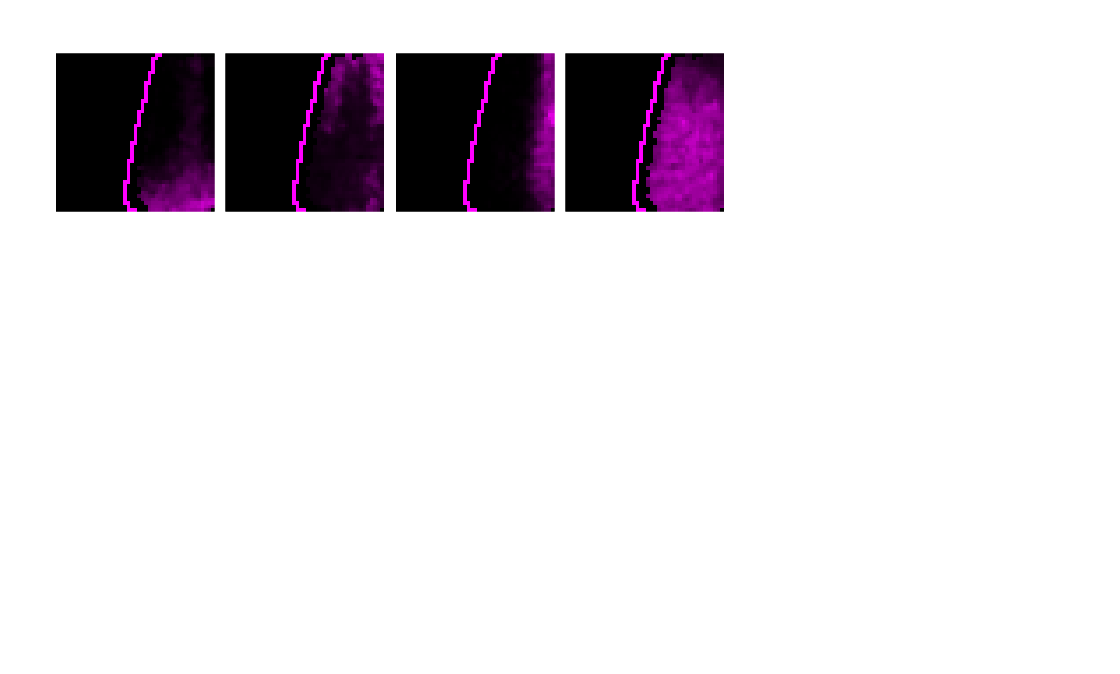

ap_pos_by_gene = zeros(length(gene_ids), 2);
ap_exp_thres = 0.2;
clipped_npsignal_spx = [];
f = figure; 
for gn = 1:size(clipped_npsignal, 3)
    %spx_map = create_superpixels(clipped_nptf(:, :, gn), [], bs);
    [spx_map, spx_std] = create_superpixels(clipped_npsignal(:, :, gn), clipped_std(:, :, gn), bs);

%     spx_map_filt = medfilt2(spx_map, [2 2]);
%     spx_map_filt(:, end - 2:end) = spx_map(:, end - 2:end);
%     spx_map_filt(1:2, :) = spx_map(1:2, :);
%     spx_map_filt(end - 2:end, :) = spx_map(end - 2:end, :);
%     spx_map = spx_map_filt;

    lm_cutoff = 10; 
    if ~isempty(find(max(spx_map(:, 1:end-lm_cutoff), [], 2) > ap_exp_thres, 1, 'last'))
        ap_pos_by_gene(gn, 1) = find(max(spx_map(:, 1:end-lm_cutoff), [], 2) > ap_exp_thres, 1, 'last');
    end

    if ~isempty(find(max(spx_map(:, end - lm_cutoff:end), [], 2) > ap_exp_thres, 1, 'last'))
        ap_pos_by_gene(gn, 2) = find(max(spx_map(:, end - lm_cutoff:end), [], 2) > ap_exp_thres, 1, 'last');
    end
    
    %ap_pos_by_gene(gn) = find(mean(spx_map, 2, 'omitnan') > ap_exp_thres, 1, 'last');
    lat_im = 0*spx_map; med_im = 0*spx_map;
    lat_im(max([ap_pos_by_gene(gn, 1), 1]), :) = 1;
    med_im(max([ap_pos_by_gene(gn, 2), 1]), :) = 1;

    % if std map created from superpixelated version
    %spx_std = std_nptf(:, :, gn);
    %spx_std = spx_std(:, 1:size(spx_std, 2)/2);

    % build superpixel by gene matrix
    spx_by_gene(:, gn) = reshape(spx_map, [], 1);
    std_by_gene(:, gn) = reshape(spx_std, [], 1);

    % sox19 outline
    filtered_im = imfilter(spx_sox19, fspecial('average', 5));
    spx_sox19_mask = logical(mat2gray(filtered_im, [0.1 0.6]));
    np_outline = imdilate(spx_sox19_mask, strel('square', 3)) - spx_sox19_mask;

    npsignal_superpix = cat(3, npsignal_superpix, spx_map);
    std_superpix = cat(3, std_superpix, spx_std);
    subtightplot(3, 6, gn); 
    %rgb_im = cat(3, spx_map + lat_im + med_im + np_outline, 0*spx_map + med_im + np_outline, spx_map + lat_im + med_im + np_outline);
    spx_map_temp = spx_map;
    spx_map_temp(isnan(spx_map_temp)) = 0;
    rgb_im = cat(3, spx_map_temp +  np_outline, 0*spx_map + np_outline, spx_map_temp + np_outline);
       
    imshow(rgb_im)


    %imshow(masked_atlas_nptf(:, :, gn), []);
end

%saveas(f, fullfile(plot_dir, 'superpixelated_maps_with_ap.svg'));


nan_values = 0*spx_by_gene;
nan_values(isnan(spx_by_gene)) = 1;
valid_rows = find(~ismember(nan_values, ones(1, size(nan_values, 2)), 'rows'));
spx_by_gene = spx_by_gene(valid_rows, :);
std_by_gene = std_by_gene(valid_rows, :);

[r, c] = ind2sub(size(spx_map), valid_rows);
spx_pos = [r, c];

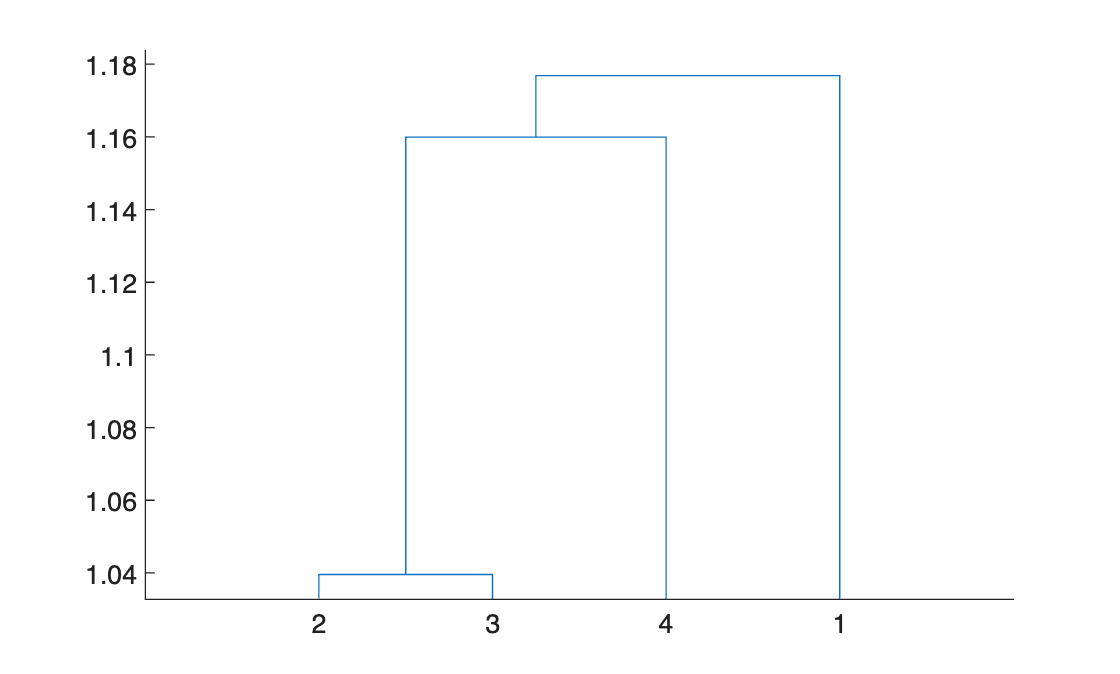

% PCA
f1 = figure;
[coeff, score, ~, ~, explained] = pca(spx_by_gene);

comp_colormap = zeros(100, 3);
for r = 1:50
    comp_colormap(r, :) = [(50 - r)/50, 0, (50 - r)/50];
end
for r = 51:100
    comp_colormap(r, :) = [(r - 50)/50, (r - 50)/50, 0];
end
colormap(comp_colormap)

subplot(2, 2, 1); 
%colormap(hot)
imagesc(coeff, [-0.6 0.6]);
%xticks([1, 5, 10, 15]);
xlabel('Principal component')
yticks(1:length(gene_names)); yticklabels(gene_names); colorbar();
subplot(2, 2, 2); 
plot(0:size(spx_by_gene, 2), [0, cumsum(explained)'], 'bo-'); ylabel('Percent variability explained'); 
xlabel('Principal component')

subplot(2, 2, 3);
[gene_names_az, sort_order] = sort(gene_names);

imagesc(coeff(sort_order, :)', [-0.6 0.6]);
%yticks([1, 5, 10, 15]);
ylabel('Principal component')
xticks(1:length(gene_names)); xticklabels(gene_names_az); colorbar();


rng('default');
comp_links = linkage(pdist(coeff(:, 1:3)));
f2 = figure;
[~, ~, pca_gene_order] = dendrogram(comp_links);

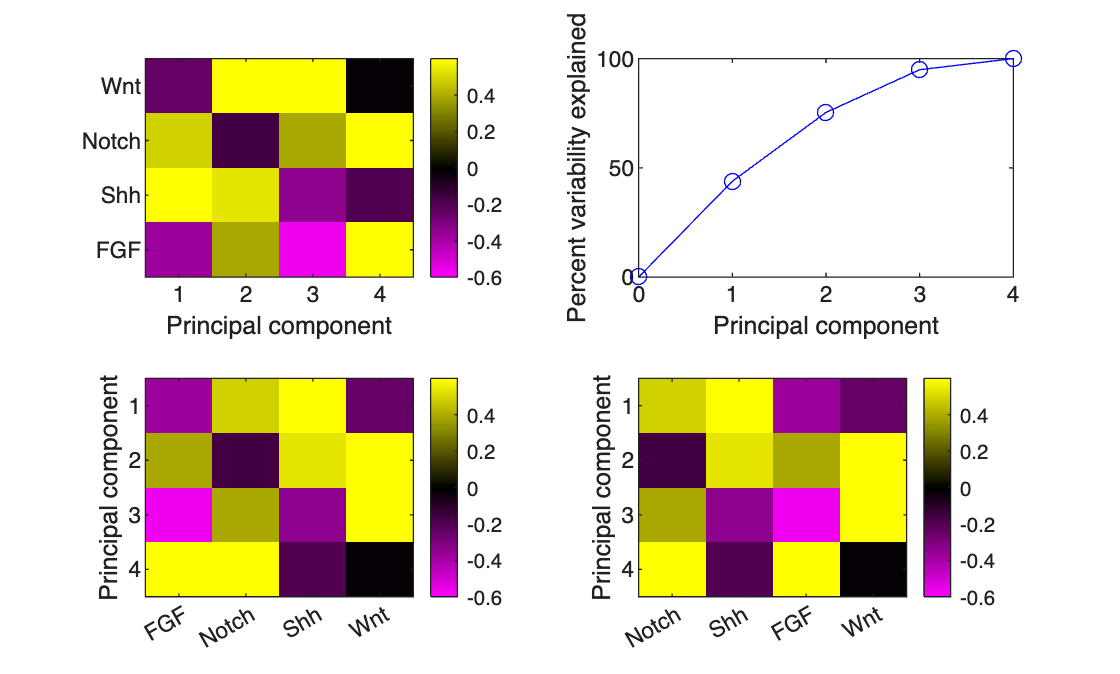


figure(f1)
subplot(2, 2, 4);
imagesc(coeff(pca_gene_order, :)', [-0.6 0.6]);
%yticks([1, 5, 10, 15]);
ylabel('Principal component')
xticks(1:length(gene_names)); xticklabels(gene_names(pca_gene_order)); colorbar();
saveas(f1, fullfile(plot_dir, 'signaling_PCA_components.svg'))



%subplot(2, 2, 2); biplot(coeff(:, [1, 2]),'scores',score(:, [1, 2]),'varlabels', gene_names);
%subplot(2, 2, 3); biplot(coeff(:, [1, 3]),'scores',score(:, [1, 3]),'varlabels', gene_names);
%subplot(2, 2, 4); biplot(coeff(:, [2, 3]),'scores',score(:, [2, 3]),'varlabels', gene_names);


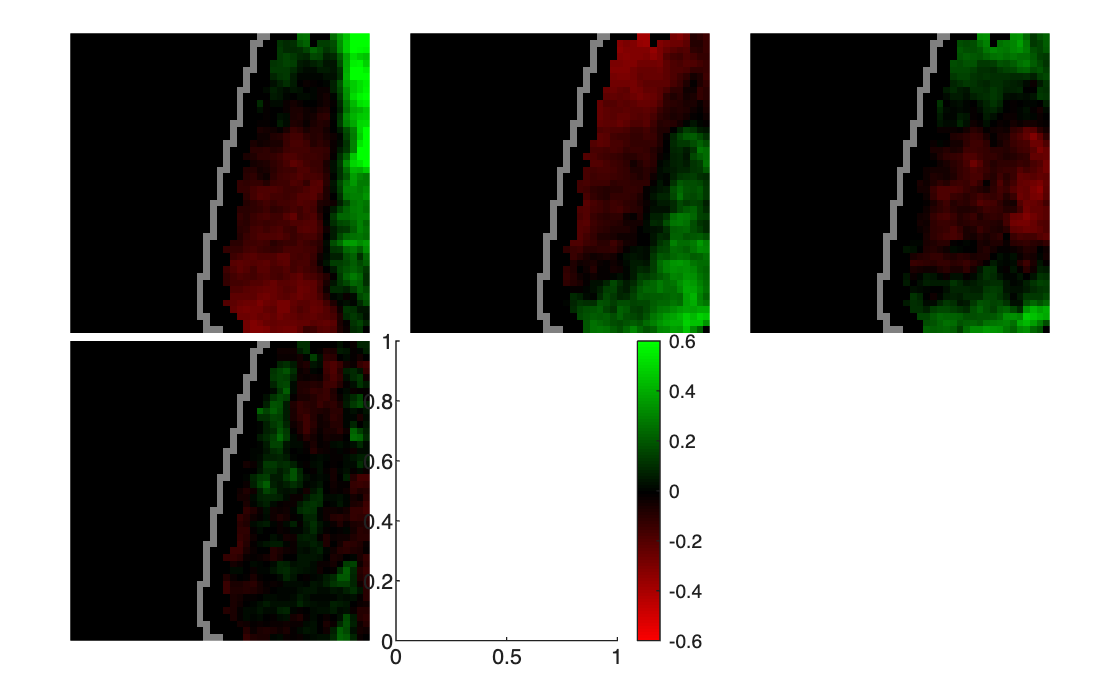

f2 = figure; 
pca_colormap = zeros(100, 3);
for r = 1:50
    pca_colormap(r, :) = [(50 - r)/50, 0, 0];
end
for r = 51:100
    pca_colormap(r, :) = [0, (r - 50)/50, 0];
end
colormap(pca_colormap)

% sox19 outline
filtered_im = imfilter(spx_sox19, fspecial('average', 5));
spx_sox19_mask = logical(mat2gray(filtered_im, [0.1 0.6]));
np_outline = imdilate(spx_sox19_mask, strel('square', 3)) - spx_sox19_mask;
%np_outline = imdilate(logical(spx_sox19), strel('square', 3)) - logical(spx_sox19);

%imshow(np_outline)

for comp = 1:4
    subtightplot(2, 3, comp); 
    temp = ones(size(spx_map))/2;
    for p = 1:size(spx_pos, 1)
        temp(spx_pos(p, 1), spx_pos(p, 2)) = (score(p, comp) + 1)/2;
    end
    rgb_temp = ind2rgb(gray2ind(mat2gray(temp, [0.2 0.8]), size(pca_colormap, 1)), pca_colormap);
   
    for ch = 1:3
        rgb_temp(:, :, ch) = rgb_temp(:, :, ch) + np_outline/2;
    end
    
    imshow(rgb_temp); 
    xticks(''); yticks('')
end
subtightplot(2, 3, 5); 
c = colorbar();
c.Ticks = 0:(1/6):1;
c.TickLabels = string(-0.6:0.2:0.6);
saveas(f2, fullfile(plot_dir, 'signaling_pca_modes.svg'));

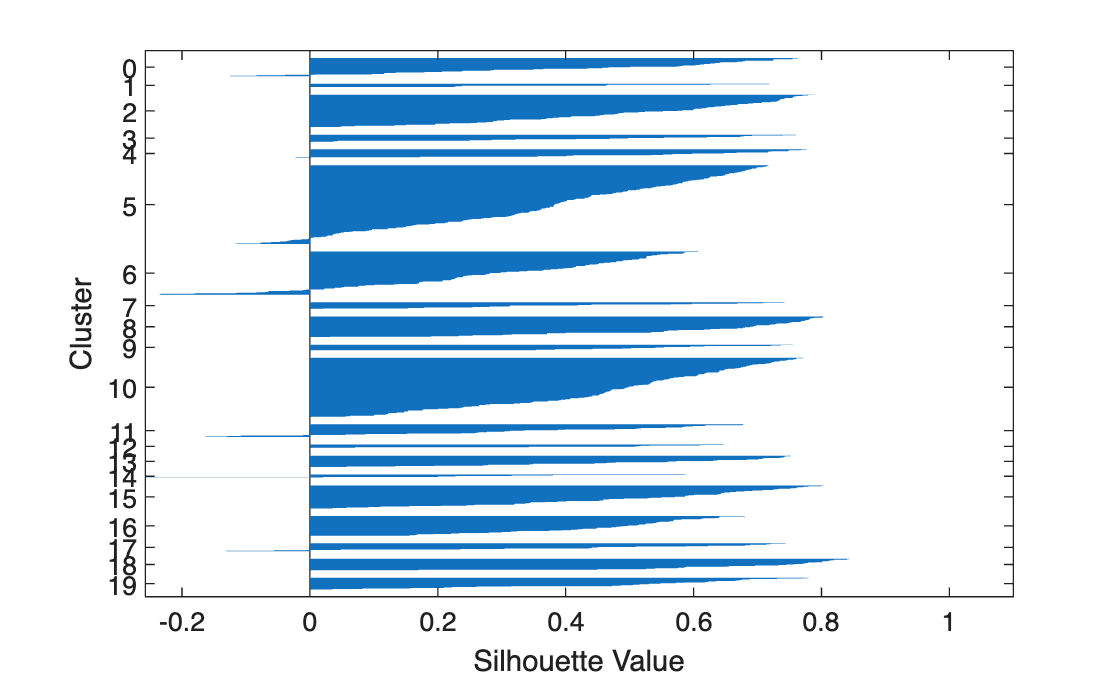

f = figure;
tot_clusters = 20;
s_values = zeros(1, tot_clusters);
gene_max_mean = zeros(length(gene_names), tot_clusters);
gene_min_mean = zeros(length(gene_names), tot_clusters);
% alternative clustering
for k = 1:tot_clusters
    num_clusters  = k;
    rng('default');
    clusterIdentifiers = kmeans(spx_by_gene, num_clusters) - 1;
    [s, h] = silhouette(spx_by_gene, clusterIdentifiers);
    s_values(k) = sum(s);

    gene_means_k = zeros(length(gene_names), k);    
    for i = 1:k
        idx = find(clusterIdentifiers == i - 1);
        gene_means_k(:, i) = mean(spx_by_gene(idx, :), 1)';
    end
    gene_max_mean(:, k) = max(gene_means_k, [], 2);
    gene_min_mean(:, k) = min(gene_means_k, [], 2);

end

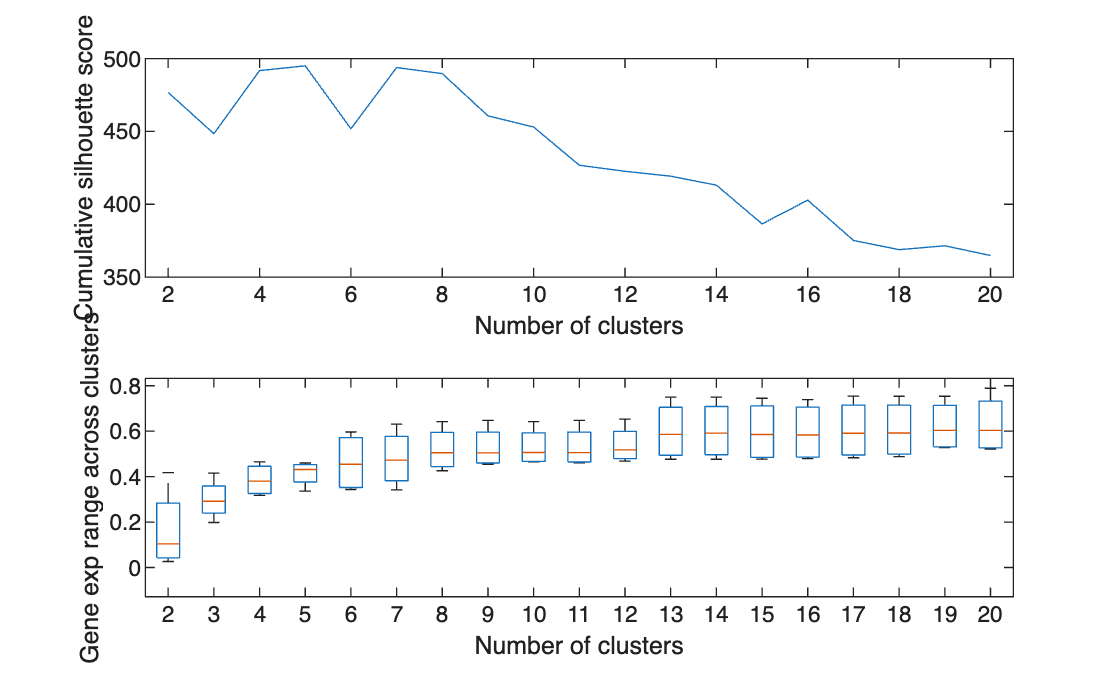

f = figure; 
subplot(2, 1, 1); plot(1:tot_clusters, s_values); xlim([1.5, 20.5])
ylabel('Cumulative silhouette score'); xlabel('Number of clusters');
subplot(2, 1, 2); boxplot(gene_max_mean - gene_min_mean); xlim([1.5, 20.5])
ylabel('Gene exp range across clusters'); xlabel('Number of clusters');
saveas(f, fullfile(plot_dir, 'signaling_silhoutte_v_diversity.svg'))

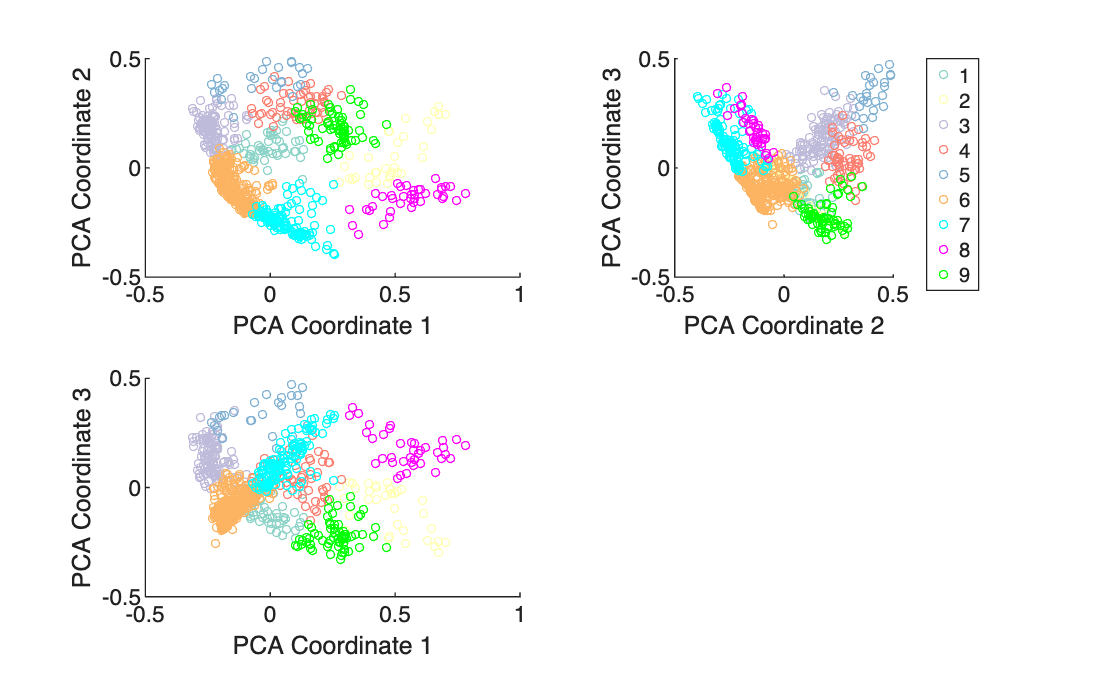

num_clusters = 9;  
cluster_colors = cbrewer2('Set3', 6);
cluster_colors = cat(1, cluster_colors, [0 1 1; 1 0 1; 0 1 0; 0 0 1]);
%rand_seed = rng('shuffle');
%cluster_colors = cluster_colors(randperm(num_clusters), :);

rng('default');
clusterIdentifiers = kmeans(spx_by_gene, num_clusters) - 1;
f1 = figure; 


cluster_labels = unique(clusterIdentifiers);
for cn = 1:length(cluster_labels)
   subplot(2, 2, 1); hold on;
%    plot3(score(clusterIdentifiers == cluster_labels(cn), 1), score(clusterIdentifiers == cluster_labels(cn), 2), ...
%       score(clusterIdentifiers == cluster_labels(cn), 3), 'Marker', 'o', 'LineStyle', 'none', 'Color', cluster_colors(cn, :));
    plot(score(clusterIdentifiers == cluster_labels(cn), 1), score(clusterIdentifiers == cluster_labels(cn), 2), ...
        'Marker', 'o', 'LineStyle', 'none', 'Color', cluster_colors(cn, :), 'MarkerSize', 3);
    xlabel('PCA Coordinate 1');
    ylabel('PCA Coordinate 2');

     subplot(2, 2, 3); hold on;
     plot(score(clusterIdentifiers == cluster_labels(cn), 1), score(clusterIdentifiers == cluster_labels(cn), 3), ...
         'Marker', 'o', 'LineStyle', 'none', 'Color', cluster_colors(cn, :), 'MarkerSize', 3);
     xlabel('PCA Coordinate 1');
     ylabel('PCA Coordinate 3');

     subplot(2, 2, 2); hold on;
     plot(score(clusterIdentifiers == cluster_labels(cn), 2), score(clusterIdentifiers == cluster_labels(cn), 3), ...
         'Marker', 'o', 'LineStyle', 'none', 'Color', cluster_colors(cn, :), 'MarkerSize', 3);
     xlabel('PCA Coordinate 2');
     ylabel('PCA Coordinate 3');


end
axis square
legend(string(cluster_labels + 1), 'Location', 'eastoutside');

saveas(f1, fullfile(plot_dir, 'signaling_pca_plot.svg'))

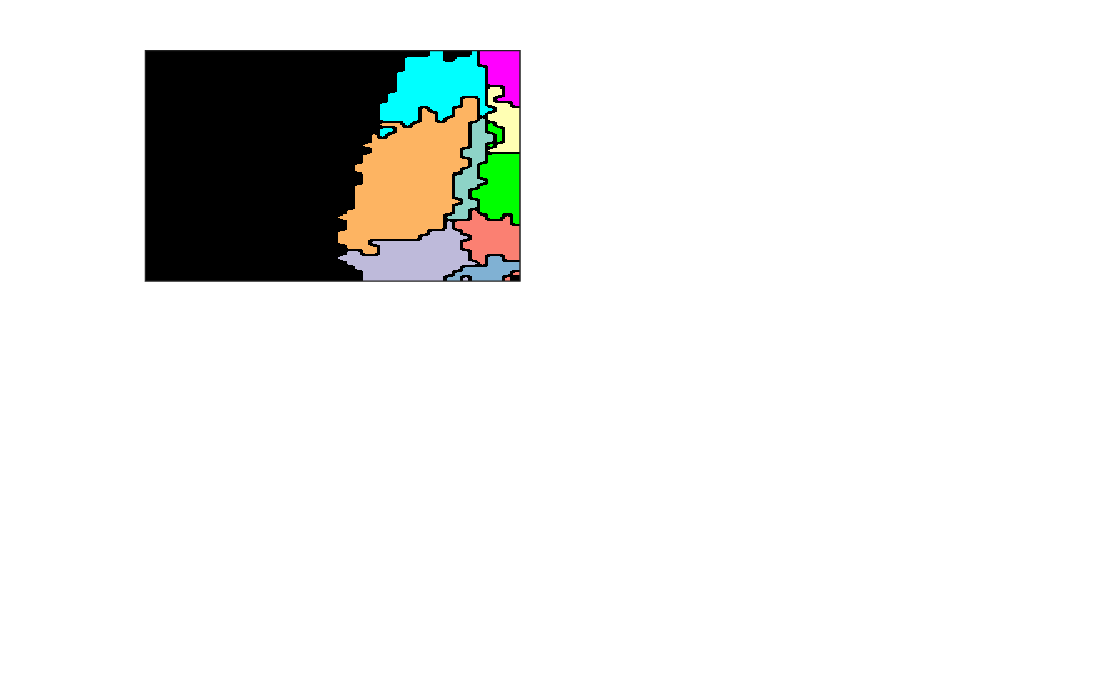

%saveas(f1, fullfile(plot_dir, 'pca_plot_w_silhouette.svg'));

f1 = figure;
cluster_map = zeros(size(spx_map));
cluster_map_rgb = repmat(0*spx_map, 1, 1, 3);
pca_pos_map = repmat(0*spx_map, 1, 1, 3);   
pca_xmin = min(score(:, 1)); pca_xmax = max(score(:, 1));
pca_ymin = min(score(:, 2)); pca_ymax = max(score(:, 2));
pca_zmin = min(score(:, 3)); pca_zmax = max(score(:, 3));

for p = 1:size(spx_pos, 1)
    px_color = cluster_colors(find(cluster_labels == clusterIdentifiers(p)), :);
    cluster_map(spx_pos(p, 1), spx_pos(p, 2)) = clusterIdentifiers(p) + 1;
    cluster_map_rgb(spx_pos(p, 1), spx_pos(p, 2), :) = px_color; 
    pca_pos_map(spx_pos(p, 1), spx_pos(p, 2), :) = [(score(p, 1) - pca_xmin)/(pca_xmax - pca_xmin), (score(p, 2) - pca_ymin)/(pca_ymax - pca_ymin), (score(p, 3) - pca_zmin)/(pca_zmax - pca_zmin)];
end

outlined_cluster_map_rgb =  zeros(5*size(cluster_map, 1), 5*size(cluster_map, 2), 3); %0*cluster_map_rgb; %
%rsz_cluster_map = imresize(cluster_map, 2);
for cn = 1:num_clusters
    temp = 0*cluster_map;
    temp(cluster_map == cn) = 1;
    temp = imresize(logical(temp), 5);
    temp_erode = imerode(temp, strel('square', 3));
    %temp_erode = temp - temp_erode; %imerode(temp_erode, strel('square', 3));
    cc = cluster_colors(cn, :);
    outlined_cluster_map_rgb = outlined_cluster_map_rgb + cat(3, cc(1)*temp_erode, cc(2)*temp_erode, cc(3)*temp_erode);
end


subplot(2, 2, 1); 
imagesc(outlined_cluster_map_rgb);
xticks(''); yticks('');
%subplot(1, 2, 2); imagesc(pca_pos_map(:, end:-1:1, :));
saveas(f1, fullfile(plot_dir, 'signaling_state_map_rgb.svg'))

## Cluster markers

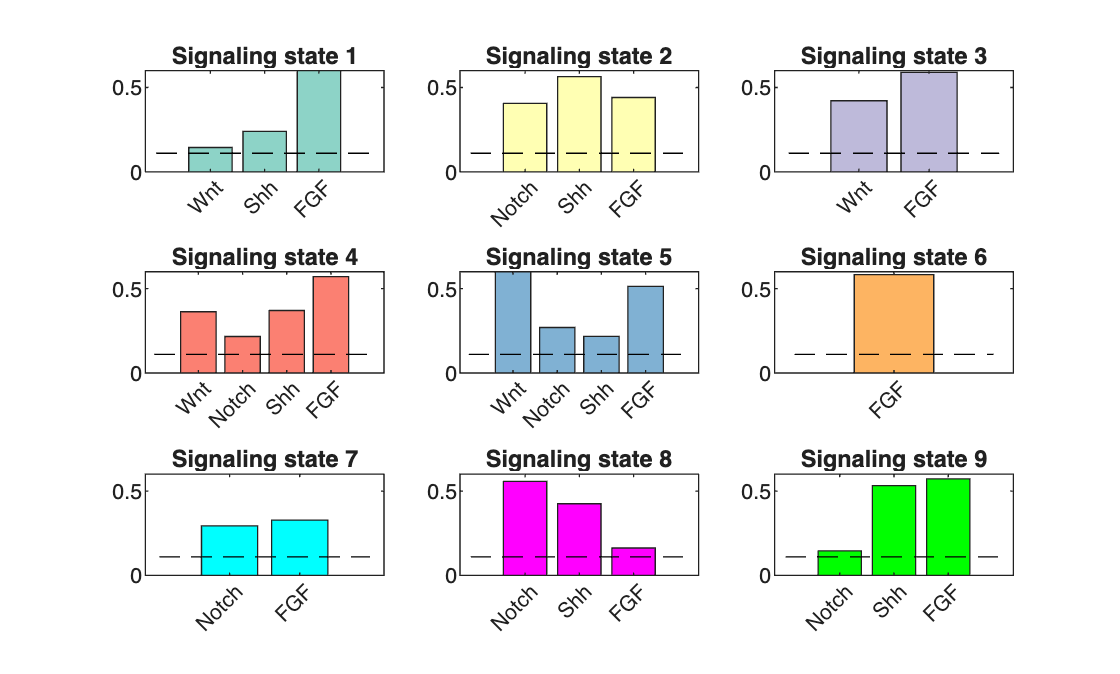

props = regionprops(cluster_map, {'Centroid', 'PixelList'});
centroids = cat(1, props.Centroid);
[sorted_centroids, sort_order] = sortrows(fliplr(centroids));
props = props(sort_order);
if mod(length(sort_order), 2) ~= 0
    sort_order = [sort_order; sort_order(end)];
end
label_grid = reshape(sort_order, 2, [])';
new_label_grid = 0*label_grid;

for r = 1:size(label_grid, 1) 
    [~, order] = sortrows(fliplr(centroids(label_grid(r, :), :)), 2);
    new_label_grid(r, :) = label_grid(r, order);
end

f2 = figure;
exp_thres = 0.11;
gene_x_cluster_matrix = [];
for cn = 1:length(cluster_labels)
    pn = cn;
%     if (cn >= 3) && (cn < 5)
%         pn = cn + 1;
%     elseif cn >= 5
%         pn = pn + 2;
%     end
    subplot(3, 3, pn);  
    mean_vals_by_gene = mean(spx_by_gene(clusterIdentifiers == cluster_labels(cn), :));
    gene_x_cluster_matrix(end + 1, :) = mean_vals_by_gene;
    exp_gene_idx = find(mean_vals_by_gene > exp_thres);
    b = bar(mean_vals_by_gene(exp_gene_idx));
    b.FaceColor = cluster_colors(cn, :);
    %hold on;
    %errorbar(1:length(gene_names), mean(spx_by_gene(clusterIdentifiers == cluster_labels(cn), :)), mean(std_by_gene(clusterIdentifiers == cluster_labels(cn), :)), 'LineStyle', 'none')
    xticks(1:length(exp_gene_idx))
    xticklabels(gene_names(exp_gene_idx));
    xtickangle(45)
    ylim([0 0.6]);
    line([0 length(gene_names(exp_gene_idx)) + 1], [exp_thres exp_thres], 'LineStyle', '--', 'Color', 'black')
    title(['Signaling state ', num2str(cn)])
end
saveas(f2, fullfile(plot_dir, ['signaling_state_markers_thres', num2str(exp_thres), '.svg']))

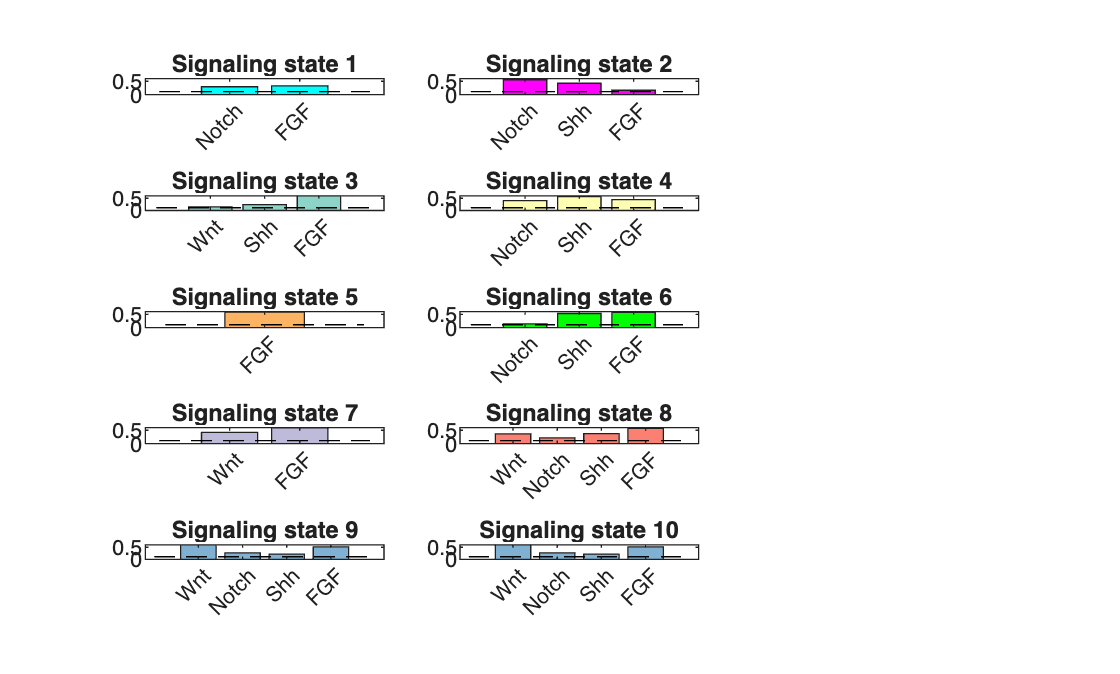

f3 = figure;
i = 1;
for r = 1:5
    for c = 1:2
        pn = i;
        if (i >= 3) && (i < 5)
            pn = i + 1;
        elseif i >= 5 && (i < 7)
            pn = pn + 2;
        elseif i >= 7 && (i < 9)
            pn = pn + 3;
        elseif i >= 9
            pn = pn + 4;
       end
        subplot(size(new_label_grid, 1), size(new_label_grid, 2) + 1, pn);
        cn = new_label_grid(r, c);
        exp_gene_idx = find(gene_x_cluster_matrix(cn, :) > exp_thres);
        b = bar(gene_x_cluster_matrix(cn, exp_gene_idx));
        b.FaceColor = cluster_colors(cn, :);
        xticks(1:length(exp_gene_idx))
        xticklabels(gene_names(exp_gene_idx));
        xtickangle(45)
        ylim([0 0.6]);
        line([0 length(gene_names(exp_gene_idx)) + 1], [exp_thres exp_thres], 'LineStyle', '--', 'Color', 'black')
        title(['Signaling state ', num2str(i)])    
        i = i + 1;
    end
end
saveas(f3, fullfile(plot_dir, 'signaling_state_markers_APML_ordered.svg'))

% save cluster ids as per apml arrangement
apml_cluster_ids = 0*clusterIdentifiers;
new_labels = reshape(transpose(new_label_grid), [], numel(new_label_grid));
new_labels = new_labels(1:num_clusters);
for i = 1:length(unique(clusterIdentifiers))
    apml_cluster_ids((clusterIdentifiers) == i - 1) = find(new_labels == i);
end
signaling_states_struct = struct();
signaling_states.spx_pos = spx_pos;
signaling_states.cluster_ids = apml_cluster_ids;
signaling_states.sig_cluster_colors = cluster_colors(new_labels, :);
save('signaling_states_data.mat', 'signaling_states');